**Rozkład F-Snedecora**

Zmienna losowa utworzona jako:


$$F=\frac{\frac{\chi_1^2 }{k_1 }}{\frac{\chi_2^2 }{k_2 }}$$


ma rozkład **F**-Snedecora z liczbą stopni swobody równą $k_1$dla licznika, oraz $k_2$ dla mianownika, gdzie $\chi_1^2$ i $\chi_2^2$ to zmienne losowe o rozkładzie chi-kwadrat.

Użycie funkcji [fpdf](https://www.mathworks.com/help/releases/R2020a/stats/fpdf.html) - funkcja gęstości prawdopodobieństawa rozkładu **F-Snedecora **(*F probability density function*)

Wartość oczekiwana wynosi:


$$E\left(F\right)=\frac{k_2 }{k_2 -2},{\;k}_2 >2$$


wariancja


$$D^2 \left(F\right)=\frac{2k_2^2 \left(k_1 +k_2 -2\right)}{k_1 {\left(k_2 -2\right)}^2 \left(k_2 -4\right)}$$

$$,{\;k}_2 >4$$


Przykład 1 Wykres pdf i cdf rozkładu F-Snedecora

clear all; close all; clc; clearvars
x1 = 0:0.1:10;
k1=5

k1 = 5

k2=8

k2 = 8

%y1 = fpdf(x1,k1,k2);
y1 = pdf('F',x1,k1,k2);
figure (1)
plot(x1,y1,'LineWidth',2)
hold on
grid on
xlabel('obserwacje F');
ylabel('pdf(F)')


Dystrybuanta 

Funkcja [fcdf](https://www.mathworks.com/help/releases/R2020a/stats/fcdf.html) - * F* cumulative distribution function

Wywołanie funkcji:

`p = fcdf(x,k1,k2)`

`p = fcdf(x,k1,k2,'upper')`

`p = cdf('F',x,k1,k2)`

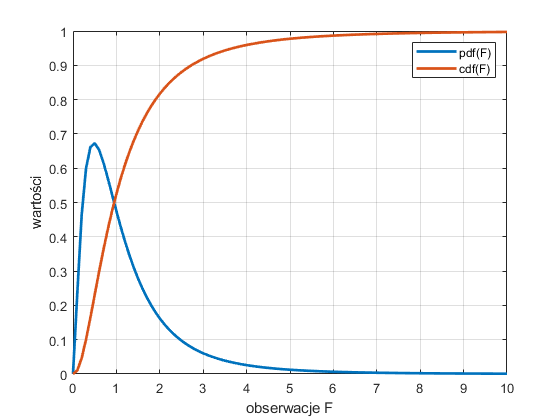

%y1 = fcdf(x1,k1,k2);
y1 = cdf('F',x1,k1,k2);

plot(x1,y1,'LineWidth',2)

ylabel('wartości')
legend('pdf(F)','cdf(F)')

Statystyka rozkładu F-Snedecora

Funkcja [fstat](https://www.mathworks.com/help/releases/R2020a/stats/fstat.html)  (*F mean and variance*) - średnia i wariancja

k1=5

k1 = 5

k2=8

k2 = 8

[m,v] = fstat(k1,k2)

m = 1.3333

v = 1.9556


[m,v] = fstat(1:5,1:5) % k1> 2 i k2 > 4

m =        NaN       NaN    3.0000    2.0000    1.6667


v =        NaN       NaN       NaN       NaN    8.8889


`Przykład 2`

Oblicz  prawdopodobienstwo P(F$\le$1,8)

k1=15

k1 = 15

k2=20

k2 = 20

xp2=1.8

xp2 = 1.8000

yp2=fcdf(xp2,k1,k2) %dystrybuanta

yp2 = 0.8908

Wizualizacja

x2 = 0:0.1:10;
k1=15

k1 = 15

k2=20

k2 = 20

y2 = fpdf(x2,k1,k2);
figure (2)
plot(x2,y2,'LineWidth',2)
hold on
xp2=1.8

xp2 = 1.8000

a1 = [xp2 xp2];
b1 = [0 fpdf(xp2,k1,k2)];
plot(xp2,fpdf(xp2,k1,k2),'r*')
line(a1,b1,'Color','red','LineStyle','-','LineWidth',2)
t = 0:0.1:xp2

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000


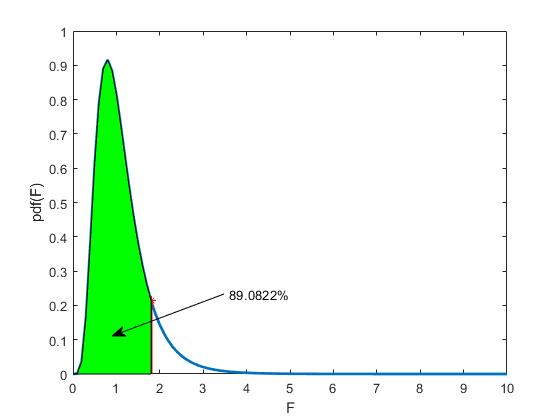

y = fpdf(t,k1,k2);
area(t,y,'FaceColor','g');
xlabel('F');
ylabel('pdf(F)');

x = [0.4 0.2];
y = [0.3 0.2];
annotation('textarrow',x,y,'String',string(yp2*100)+ '%')

Przykład 3

Oblicz P(F$\ge$1,8) dla zmiennej losowej o rozkładzie F-Snedecora z liczbą stopni swobody równą 15 dla licznika oraz 20 dla mianownika

k1=15

k1 = 15

k2=20

k2 = 20

xp3=1.8

xp3 = 1.8000

yp3a=1-fcdf(xp3,k1,k2)

yp3a = 0.1092

yp3b=fcdf(xp3,k1,k2,'upper') % "ogon rozkładu po prawej stronie

yp3b = 0.1092

wizualizacja

x3 = 0:0.1:10;
k1=15

k1 = 15

k2=20

k2 = 20

y3 = fpdf(x3,k1,k2);
figure (3)
plot(x3,y3,'LineWidth',2)
hold on
grid on
xp3=1.8

xp3 = 1.8000

a1 = [xp3 xp3];
b1 = [0 fpdf(xp3,k1,k2)];
plot(xp3,fpdf(xp3,k1,k2),'r*')
line(a1,b1,'Color','red','LineStyle','-','LineWidth',2)
t = xp3:0.1:max(x3)

t =     1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000    6.0000    6.1000    6.2000    6.3000    6.4000    6.5000    6.6000    6.7000


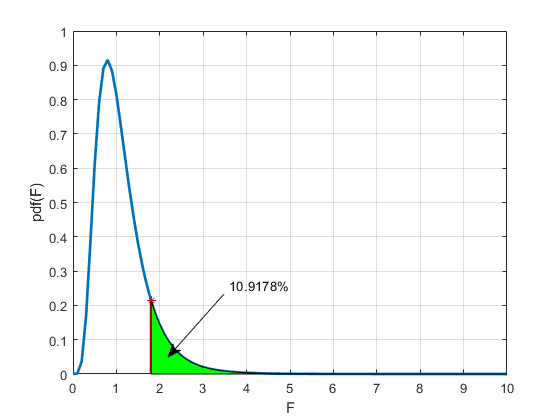

y = fpdf(t,k1,k2);
area(t,y,'FaceColor','g');
xlabel('F');
ylabel('pdf(F)');
x = [0.4 0.3];
y = [0.3 0.15];
annotation('textarrow',x,y,'String',string(yp3b*100)+ '%')

Przykład 4

Oblicz P(F$\le$0,7) dla zmiennej losowej o rozkładzie F-Snedecora z liczbą stopni swobody równą 15 dla licznika oraz 20 dla mianownika

xp4=0.7

xp4 = 0.7000

k1=15

k1 = 15

k2=20

k2 = 20

yp4 = fcdf(xp4,k1,k2)

yp4 = 0.2430


figure (4)
hold on
x4 = 0:0.1:10;
k1=15

k1 = 15

k2=20

k2 = 20

y4 = fpdf(x4,k1,k2);
plot(x4,y4,'LineWidth',2)
plot(xp4,fpdf(xp4,k1,k2),'r*')
a4 = [xp4 xp4];
b4 = [0 fpdf(xp4,k1,k2)];
line(a4,b4,'Color','green','LineStyle','-','LineWidth',2)

t = 0:0.1:xp4

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000


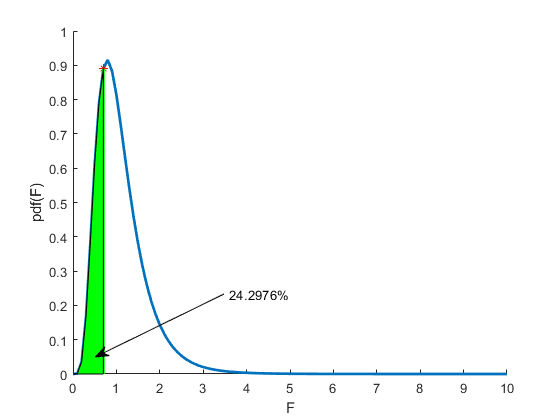

y = fpdf(t,k1,k2);
area(t,y,'FaceColor','g');
xlabel('F');
ylabel('pdf(F)');
x = [0.4 0.17];
y = [0.3 0.15];
annotation('textarrow',x,y,'String',string(yp4*100)+ '%')

Przykład 5

Zmienna losowa o rozkładzie F-Snedecora z liczbą stopni swobody równą 8 dla licznika oraz 6 dla mianownika. Oblicz:

- P(F$\ge$2,1) 

xp5=2.1

xp5 = 2.1000

k1=8

k1 = 8

k2=6

k2 = 6

y5a = 1-fcdf(xp5,k1,k2)

y5a = 0.1908

y5b = fcdf(xp5,k1,k2,'upper')

y5b = 0.1908


figure (5)
hold on
grid on
x5 = 0:0.1:10;

y5 = fpdf(x5,k1,k2);
plot(x5,y5,'LineWidth',2)
plot(xp5,fpdf(xp5,k1,k2),'r*')
a5 = [xp5 xp5];
b5 = [0 fpdf(xp5,k1,k2)];
line(a5,b5,'Color','green','LineStyle','-','LineWidth',2)

t = xp5:0.1:max(x5)

t =     2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000    6.0000    6.1000    6.2000    6.3000    6.4000    6.5000    6.6000    6.7000    6.8000    6.9000    7.0000


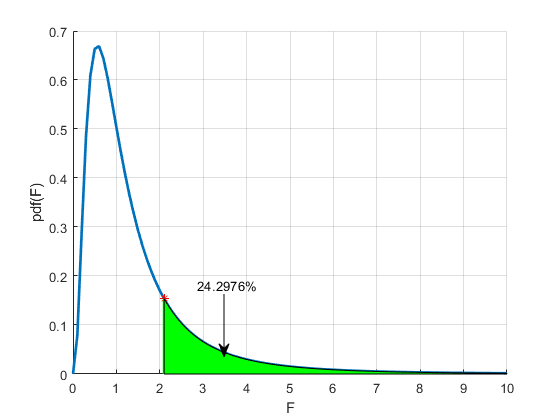

y = fpdf(t,k1,k2);
area(t,y,'FaceColor','g');
xlabel('F');
ylabel('pdf(F)');

x = [0.4 0.4];
y = [0.3 0.15];
annotation('textarrow',x,y,'String',string(yp4*100)+ '%')

Odwrotność  (*F inverse cumulative distribution function*)

Funkcja [finv](https://www.mathworks.com/help/releases/R2020a/stats/finv.html)

Przykład 6

p=0.98 %zadane prawdopodobieństwo

p = 0.9800

k1=5

k1 = 5

k2=8

k2 = 8

f6 = finv(p,k1,k2)

f6 = 5.2227

Funkcja [frnd](https://www.mathworks.com/help/releases/R2020a/stats/frnd.html)  (*F random numbers*)

k1=15

k1 = 15

k2=20

k2 = 20

losF1=frnd(k1,k2)

losF1 = 1.7272

Generator liczb losowych rozkładu F - macierz 10 x 10

losF2=frnd(k1,k2, [10 10])

losF2 =     0.2769    1.6210    0.7922    1.9373    0.8232    0.8868    0.4196    0.4061    1.0364    1.4566
    0.7153    1.4466    0.6145    0.4580    0.9806    0.4373    1.0233    1.2252    1.0170    1.4744
    1.0085    0.9240    1.6807    1.1724    1.2268    1.9338    0.5070    1.3505    1.2926    1.8470
    0.7310    0.4955    0.6771    1.0663    1.2940    0.6702    2.1970    1.7053    1.3017    0.7267
    2.0260    0.5014    0.5013    0.4398    0.6790    1.4070    1.5464    2.0984    1.1348    1.0136
    0.6996    0.6457    0.3997    0.7627    1.5863    1.1312    2.6582    1.2605    1.8736    1.3060
    1.5203    0.6186    2.2027    1.0989    0.5887    0.6915    0.8973    2.3473    1.0156    0.3573
    1.9905    0.9476    0.5784    2.0153    0.8965    1.2016    0.6941    0.5519    1.0415    0.8754
    0.9949    0.6802    1.8245    2.1290    1.1067    0.6857    0.6428    1.3711    0.4401    0.6376
    0.8274    0.7958    0.2607    0.5137    0.9084    0.4768    2.9109    0.5287   

Sterowanie generatorem liczb losowych

rng shuffle
k1=15

k1 = 15

k2=20

k2 = 20

for i=1:10
    losF1=frnd(k1,k2)
end

losF1 = 0.7112

losF1 = 1.5776

losF1 = 0.8800

losF1 = 1.4800

losF1 = 1.8206

losF1 = 4.0177

losF1 = 0.8429

losF1 = 1.4928

losF1 = 1.4382

losF1 = 0.8240